# 简单的图论问题

## 一、图的生成

- 用自己的学号作为随机数的种子初始化随机数

- 在[0, 1]2平面上随机生成200个顶点，在图形上输出这200个顶点的位置

- 如果两个顶点相邻的充要条件为：它们之间的距离不大于r（r为节点的通信半径）。试选取合适的r，使得节点的平均度约为12

- 画出生成的网络拓扑结构，要求整个网络是联通的

clear i;    % 用到复数，禁止使用 i 作为循环变量
rng(58);

N = 200;
P = rand(N,1) + i * rand(N,1);
A = repmat(P,1,N) - repmat(P.',N,1);
D = abs(A); % 任意两点之间的距离

r = 0.1482;
[as,bs] = find(D < r);  % 所有距离小于通信半径的点对
% 只保留距离小于通信半径的边
D1 = zeros(size(D));
for j = 1:length(as)
    D1(as(j),bs(j)) = D(as(j),bs(j));
end

G = graph(D1);

% 求最大连通子图
[bin,binsize] = conncomp(G);    % 每个节点所属连通分量序号及各连通分量的节点数
[N,maxI] = max(binsize);
is = bin == maxI;    % 查找所有在最大连通分量中的节点
G = subgraph(G,is);
P1 = P(is);

% 计算平均度
des = degree(G);
ave_degree = mean(des)

ave_degree = 12

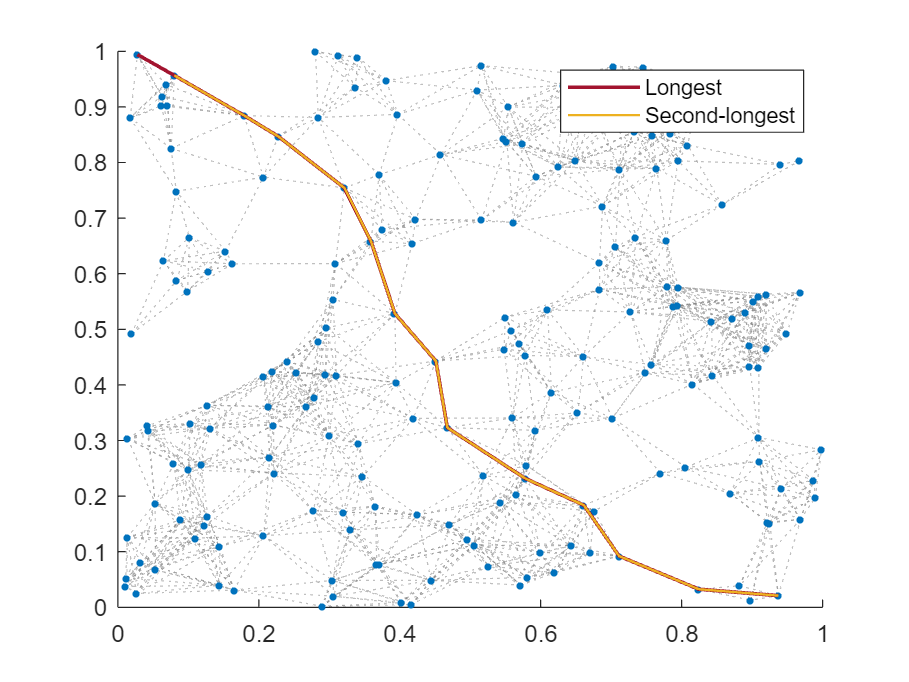


figure
plot(G,'XData',real(P1),'YData',imag(P1),'Marker','o')
xlim([0,1])
ylim([0,1])

## 二、最小生成树

- 用Prim算法计算网络的最小生成树，并在图中显示该最小生成树

% 与内置函数比较
T = minspantree(G);    % 默认minspantree(G,'Method','dense')

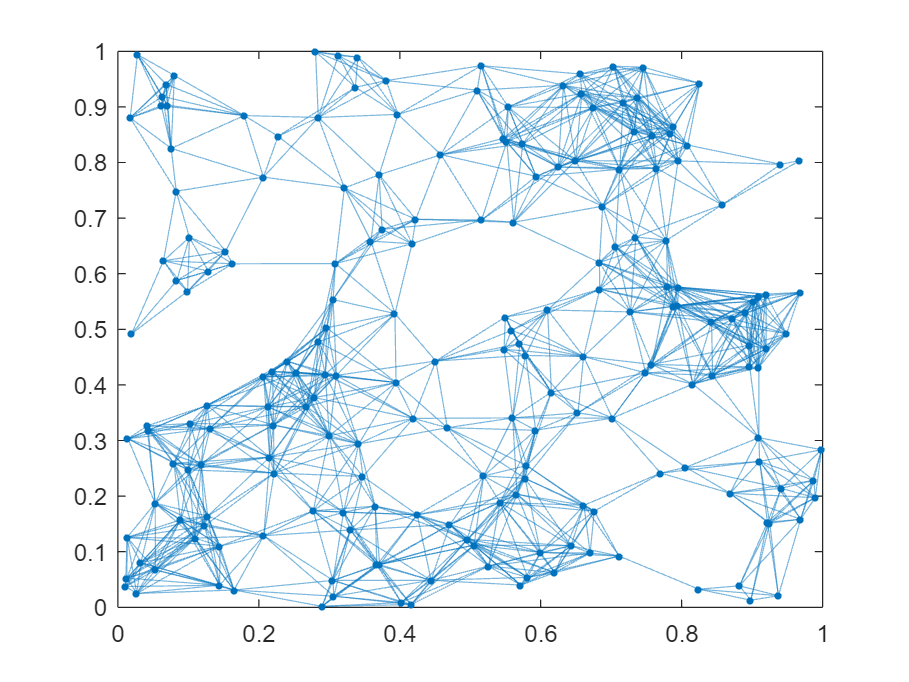

figure
hold on
plot(G,'XData',real(P1),'YData',imag(P1),'Marker','o','LineStyle',':','EdgeColor',[0.5 0.5 0.5])
xlim([0,1])
ylim([0,1])
plot(P1(T.Edges.EndNodes).','LineWidth',1,'Color','#77AC30') % 注意是非共轭转置
hold off

## 三、最短路算法

- 用Dijkstra算法计算出网络中最靠近中心的顶点到其它所有顶点之间的最短路

- 用Floyd算法计算所有节点对之间的最短路径以及最短路，并在网络中找出所有最长的和次长的路径，并用MATLAB分别在图上打印之。

minI = 1;
minlength = abs(P1(minI) - (0.5 + i*0.5));
for j = 2:N
    newlength = abs(P1(j) - (0.5 + i*0.5));
    if newlength < minlength
        minI = j;
        minlength = newlength;
    end
end

short = struct('path',{},'len',0);  % 建立空cell：{}，建立一定大小的空cell：cell(sz1,sz2)，调用：c{1,2}
for j = 1:N
    if j ~= minI
        [short(j,1).path,short(j,1).len] = shortestpath(G,minI,j,'Method','positive');   % Dijkstra
    end
end

disp(["起始点：" minI])

    "起始点："    "160"



disp([table((1:N)','VariableNames',"end point") struct2table(short)])

    end point                   path                       len     
    _________    __________________________________    ____________

         1       {[               160 2 152 167 1]}    {[  0.4170]}
         2       {[                         160 2]}    {[  0.1263]}
         3       {[              160 85 130 162 3]}    {[  0.4105]}
         4       {[        160 2 100 137 59 104 4]}    {[  0.7242]}
         5       {[            160 85 130 51 38 5]}    {[  0.4922]}
         6       {[           160 2 152 167 125 6]}    {[  0.6019]}
         7       {[                   160 2 100 7]}    {[  0.3528]}
         8       {[               160 2 100 137 8]}    {[  0.3907]}
         9       {[                  160 163 56 9]}    {[  0.2947]}
        10       {[     160 79 117 154 126 105 10]}    {[  0.5739]}
        11       {[          160 89 49 147 197 11]}    {[  0.4486]}
        12       {[    160 89 49 198 31 114 46 12]}    {[  0.6499]}
        13       {[                160 2 100 7 

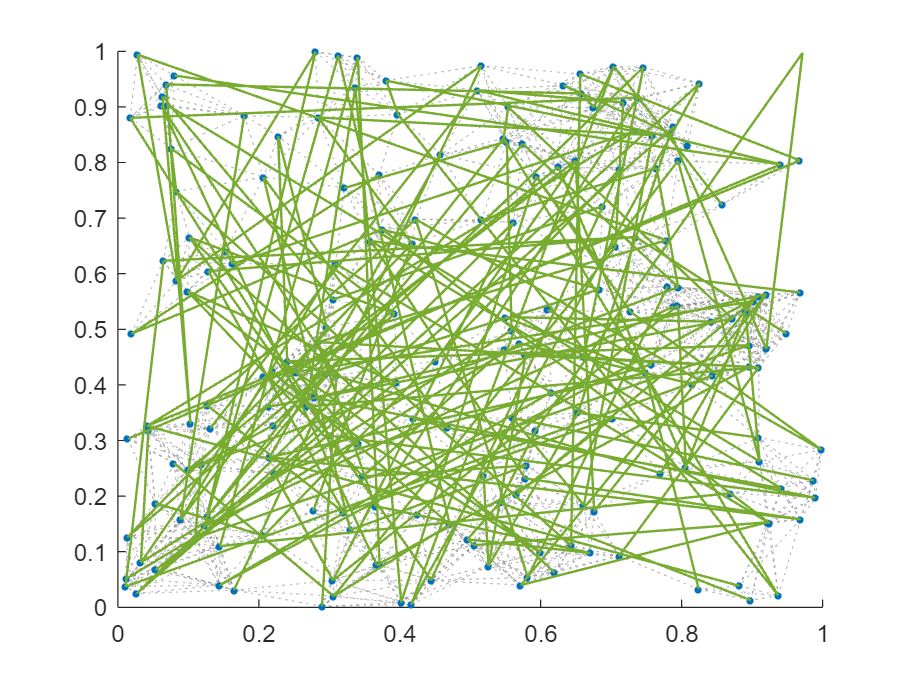



max1Ia = 1;
max1Ib = 1;
max1 = 0;
max2Ia = 1;
max2Ib = 1;
max2 = 0;
max3Ia = 1;
max3Ib = 1;
max3 = 0;

G1 = digraph(D1(is,is));
dis = distances(G1, 'Method', 'mixed'); % 求任意两节点的最短路径, 注意在有向图中来回是两条不同的路径，因此要求第三长的
for j = 1:N
    for k = (j+1):N
        if dis(j,k) > max1
            max1Ia = j;
            max1Ib = k;
            max1 = dis(j,k);
        else 
            if dis(j,k) > max2
                max2Ia = j;
                max2Ib = k;
                max2 = dis(j,k);
            else 
                if dis(j,k) > max3
                    max3Ia = j;
                    max3Ib = k;
                    max3 = dis(j,k);
                end
            end
        
        end
    end
end

figure
hold on
plot(G,'XData',real(P1),'YData',imag(P1),'Marker','o','LineStyle',':','EdgeColor',[0.5 0.5 0.5])
xlim([0,1])
ylim([0,1])

[path,~] = shortestpath(G,max1Ia,max1Ib);
plot((P1(path)).','LineWidth',1.5,'Color','#A2142F');
[path,~] = shortestpath(G,max3Ia,max3Ib);
plot((P1(path)).','LineWidth',1,'Color','#EDB120');
legend("","Longest","Second-longest")  % 背景不用图例

hold off

## 四、关键路径算法

- 将邻接矩阵的下三角或上三角部分全部清零（定义为不连通），用拓扑排序验证是否为有向无环图，若是，再计算并用MATLAB绘出其关键路径。

L = logical(triu(ones(200), 1));
D2 = D1.*L;
G2 = digraph(D2);
G2 = subgraph(G2,is);
figure
hold on
plot(G2, 'XData',real(P1),'YData',imag(P1),'Marker','o','LineStyle',':')
xlim([0,1])
ylim([0,1])

isdag(G2)

ans = logical
   1


topo = toposort(G2);
ve = Inf(199, 1);
vl = zeros(199, 1);
ve(topo(1)) = 0;
for i = topo(1:end-1)
    sucIDs = successors(G2, i);
    for j = sucIDs'
        ve(j) = min(ve(i) + D2(i, j), ve(j));
    end
end
vl(topo(end)) = ve(topo(end));
for j = topo(end:-1:2)
    sucIDs = predecessors(G2, j);
    for i = sucIDs'
        vl(i) = max(vl(j) - D2(i, j), vl(i));
    end
end
path = [];
for i = 1:199
    if ve(i) == vl(i)
        path = [path; i];
    end
end

plot(subgraph(G2, path), 'XData',real(P1(path)),'YData', imag(P1(path)), 'EdgeColor', '#EDB120');
hold off